## Random Forest Hyperparameter Search

This script performs a detailed search for the final model's hyperparameters.

### Initialise

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetNormalisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1
          isRemovedFeature: 1



### Check Random Forest Analysis Code Works

hyperParameters = RFHyperparameters.getHyperQuickInstance();

rfHyperparameters =   RFHyperparameters with properties:

      features: [2 4]
         trees: 25
         folds: [2 3]
    randomSeed: 122


rfClass = RandomForestClass(hyperParameters);
rfClass.debug = true;
results = rfClass.performAnalysis(letterDataset, "RFQuickTest.csv");

Starting Random Forest analysis...
Misclassified 178 entries out of 3200. 5.5625 pct	Training loss: 0.01. Test Loss: 0.09 Oob Error: 0.18	Precision: 0.9439 Recall: 0.9441 Accuracy: 0.9444 F1: 0.9440
	numTree 25 numFeature 2 trainErr 0.0104 testErr 0.0870 oobErr 0.1843 fold 1  of 2 predictTime 0.6200	Samples: T I D N G
Misclassified 168 entries out of 3200. 5.2500 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9472 Recall: 0.9478 Accuracy: 0.9475 F1: 0.9475
	numTree 25 numFeature 2 trainErr 0.0102 testErr 0.0846 oobErr 0.1837 fold 2  of 2 predictTime 0.4600	Samples: T I D N A
Misclassified 161 entries out of 3200. 5.0312 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9494 Recall: 0.9500 Accuracy: 0.9497 F1: 0.9497
	numTree 25 numFeature 2 trainErr 0.0104 testErr 0.0838 oobErr 0.1829 fold 1  of 3 predictTime 0.3700	Samples: T I G A M
Misclassified 145 entries out of 3200. 4.5312 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precisi

disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2        25       2              1               0.0103         0.0858          0.184        0.9459          0.9456         

### Hyperparameter Optimization Search

hyperParameters = RFHyperparameters.getHyperDefaultInstance();
rfClass = RandomForestClass(hyperParameters);
rfClass.debug = false;
results = rfClass.performAnalysis(letterDataset, "RFDefaultTest.csv");

Starting Random Forest analysis...


results = RFResults.getInstanceFromCsvResults("RFDefaultTest.csv");
disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2        50       2              1               0.0052         0.0662         0.1249        0.9544          0.9539        0

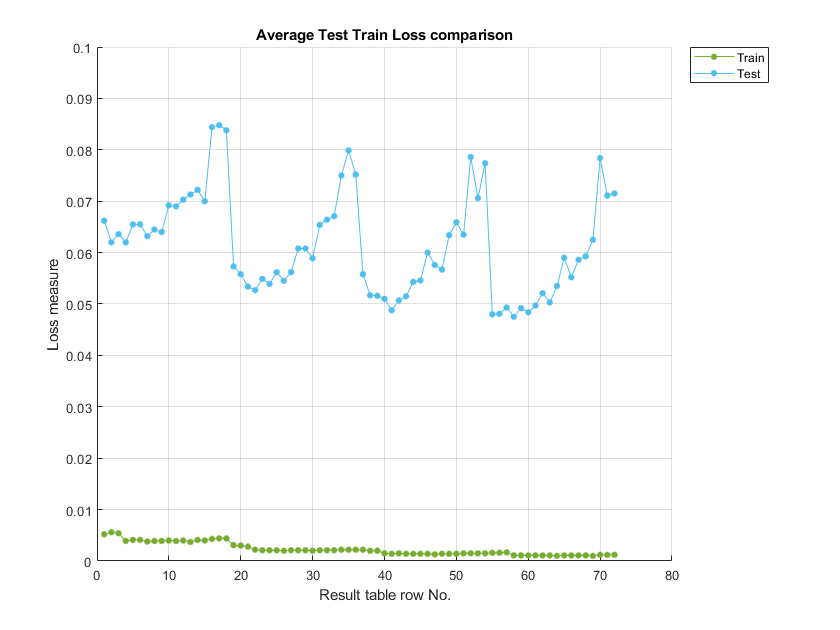

PlotUtil.plotLossTestTrainComparisonWithYMax(results.resultsTable, "Average Test Train Loss comparison", 0.1);

Rows 58, 41 and 22 look interesting: smallest loss in their group. The results for these rows is shown below:

disp(results.resultsTable([58,41,22],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       200       2             58               0.0011         0.0475         0.0658        0.9589          0.9585        0

As stated by [1] and [2], 100 trees is the minimum acceptable, more trees gives slightly better results, but takes considerably longer.

The number of folds has little effect on prediction using decision trees. Frey and Slate report that the only reason they use two folds, with this dataset, is that using one fold is not a reccomended statistical practice [3].

The number of features that perform best are 4.

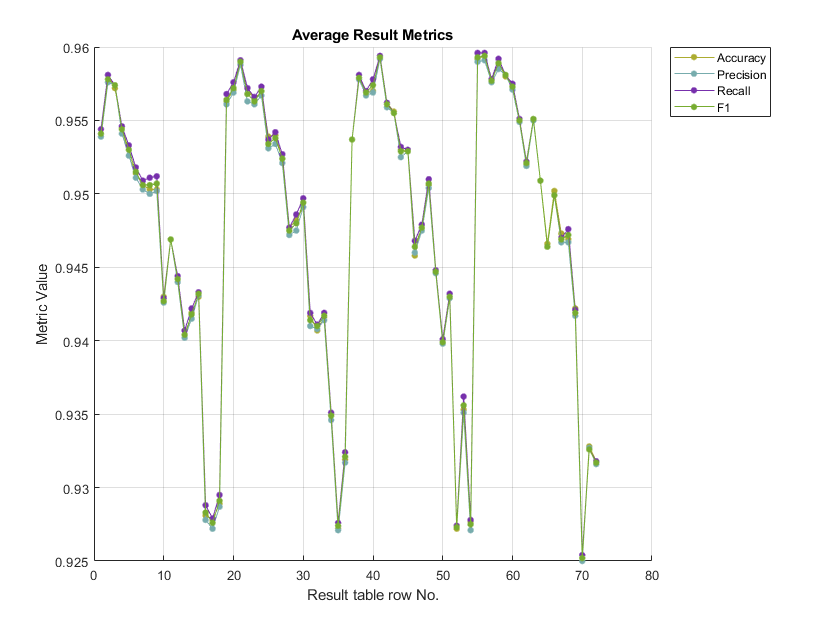

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

Rows 17, 35, 54, 70 look interesting in terms of performance, their metrics are shown below:

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       200       2             58               0.0011         0.0475         0.0658        0.9589          0.9585        0

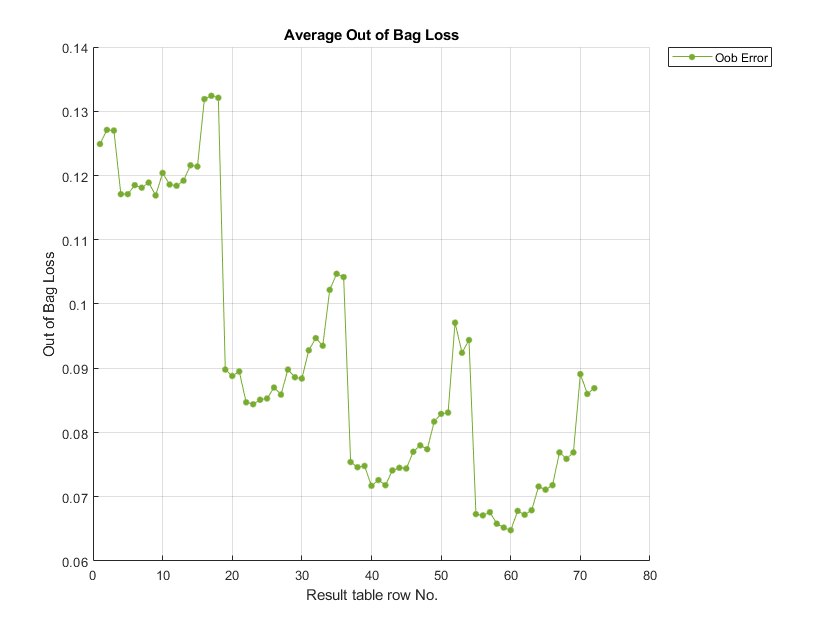

disp(results.resultsTable([58,41,22],:));

- Accuracy, precision and recall move together. 

- The best number of features is again 4. 

- The number of folds does not seem to have much effect

- 200 trees versus 100 for 2% better performance is acceptable

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2       100       3             20                0.003         0.0558         0.0888        0.9571          0.9569        0

PlotUtil.plotOob(results.resultsTable, "Average Out of Bag Loss");

Rows 40, 60 look interesting

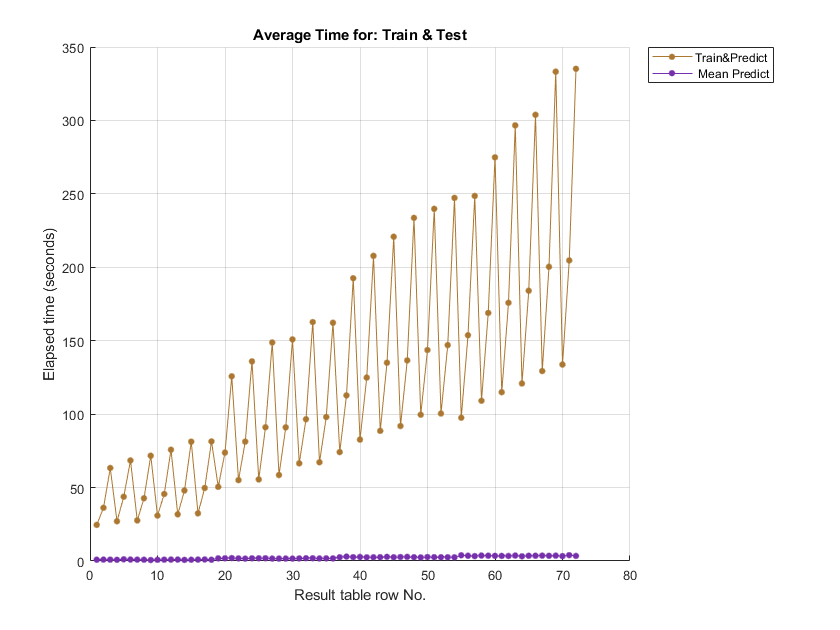

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       100       2             22               0.0022         0.0527         0.0847        0.9572          0.9563        0

disp(results.resultsTable([20, 40,60],:));

The out of bag loss and time are the two considerations: 2% less loss for approximately twice the time. 

The prediction time ranges between like the candidate to select for the number of trees.

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

A repeated pattern is apparent, with low, medium and high times. Which hyperparameter is found by looking at the details below:

disp(results.resultsTable([22,23,24],:));

The results show that the number of folds was the predominant factor for the time difference. The number of folds affects the time taken to grow the tree. The longest time to train and test the ensemble is under 2 minutes.

The perfomance metrics are tightly grouped. There is some small difference between the average test losses (0.0019)

In conclusion the hyperparameters to use for the final model are: **100 trees, 4 features, 22 as the random seed.**

### Perform final test using optimal hyperparameters on complete dataset, save the model (manually)

#### Initialise

% CLear all
clear
clc
clf
close all
% load the letter dataset 

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1



load letterDatasetClass.mat
letterDataset = letterDatasetNormalisedReducedFeatures;
disp(letterDataset);

#### Train

treeBaggerModel is the model for the random forest method that is saved manually.

[xTrain, yTrain] = letterDataset.extractXYFromTable(letterDataset.trainTable);
[treeBaggerModel, trainTime] = RandomForestClass.buildFinalRandomForest(100, 4, 22, xTrain, yTrain);

#### Test using the data not seen before

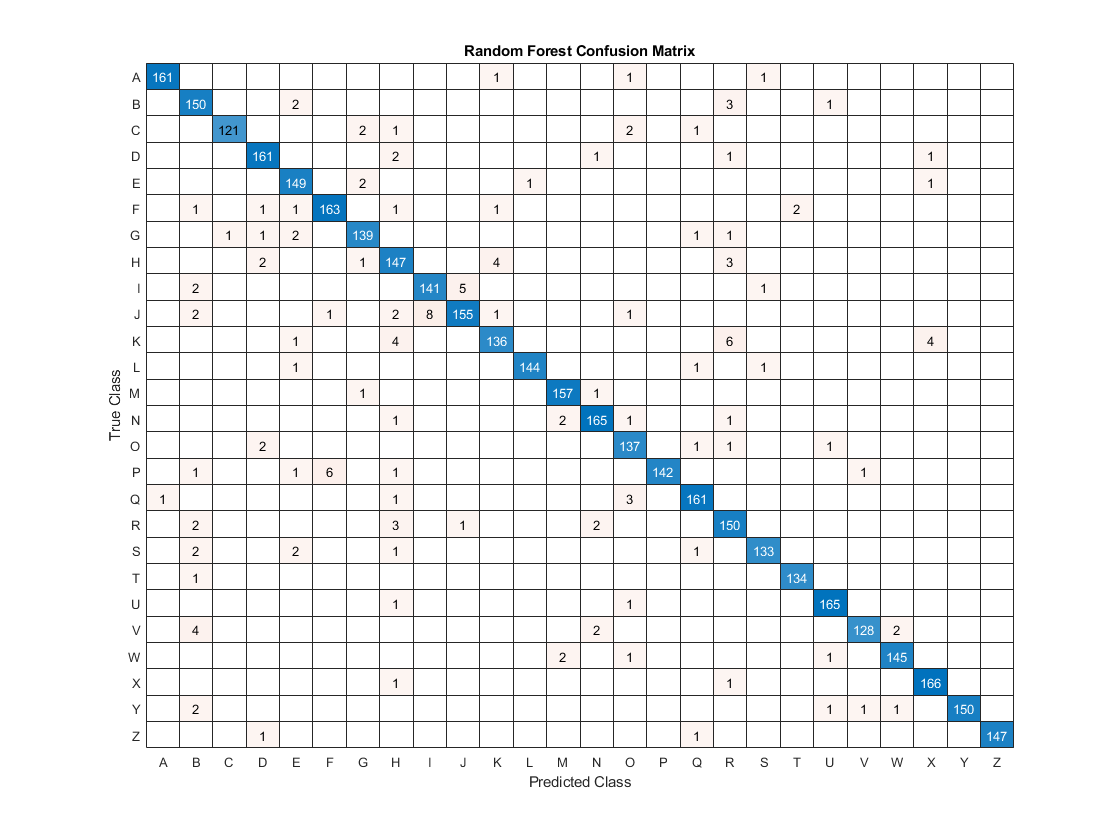

[xTest, yTest] = letterDataset.extractXYFromTable(letterDataset.testTable);
startTime = cputime;
[predictionResult, ~] = predict(treeBaggerModel, xTest(:,:));
predictTime = cputime - startTime;
% errors
misclassifiedCount = sum(predictionResult ~= categorical(table2array(yTest)));
[accuracy, precision, recall, ...
  f1] = CalcUtil.calculateMeasuresFromExpectPredict(table2array(yTest), predictionResult);
y = categorical(table2cell(yTest));

pred = categorical(predictionResult);
% Plot confusion matrix

Accuracy: 0.9617 Precision: 0.9616 Recall: 0.9630 F1 0.9623. Train time: 15.5938 Predict time: 2.4688


PlotUtil.plotConfusionChart(y, pred, "Random Forest Confusion Matrix");
fprintf("Accuracy: %0.04f Precision: %0.04f Recall: %0.04f F1 %0.04f. Train time: %0.04f Predict time: %0.04f\n", ...
  accuracy, precision, recall, f1, trainTime, predictTime);

- The results' accuracy of 0.9617 is  very good. The method is a black box method: it is not interpretable due to the large number of randomly built trees.

- The confusion matrix shows that the blue diagonal has a high proprtion of correct classifications. 

- The confusion matrix shows that 'J' and 'I' are most confused with each other.

- 'Z', 'X' and 'M' are the least overall misclassified classes.

### Notes

TreeBagger has several properties of interest:

- `NumPredictorsToSample: number of features to randomly select for each tree, default sqrt(num classes)`

- `NumTrees: the number of trees in the forest`

- `Prior: prior distribution of the classes, this is set to the empirical distribution of the entire training dataset classes.`

`Number of trees in the ensemble: Khoshgoftaar (2007) a default value of 100 for trees is good.`

`Braiman (2001): more trees will give better results without overfitting on the validation set.`

`Number of random features for splitting at each step: Khoshgoftarr (2007) (log2 * numFeatures + 1). Matlab uses sqrt(numFeatures)`

### `References`

`[1] Breiman, L., Adele Cutler, `[Random forests - classification description (berkeley.edu)](https://www.stat.berkeley.edu/~breiman/RandomForests/cc_home.htm)

[2] T. M. Khoshgoftaar, M. Golawala, and J. V. Hulse, “An Empirical Study of Learning from Imbalanced Data Using Random Forest,” 

[3] P. W. Frey and D. J. Slate, “Letter recognition using Holland-style adaptive classifiers,” *Mach. Learn.*, vol. 6, no. 2, pp. 161–182, Mar. 1991, doi: 10.1007/BF00114162.